data_filename = './sample_data/vectornav_pitch45_5_17.csv';

% Our sample data has headers on the first line, so skip it
data = csvread(data_filename, 1);

% We'll use the time that the sample starts as each time
time = data(:, 1) * 10^(-9);
time = time - time(1);

% Using the first timestamp, calculate the sampling rate.
% With the configuration for the VectorNav, this will remain consistent.
sampling_rate = 1 / (time(2) - time(1));

yaw_pitch_roll_device = data(:, 4:6);
% IMU initialized using magnetometer.  Remove this bias.
%yaw_pitch_roll_device(:, 1) = yaw_pitch_roll_device(:, 1) - yaw_pitch_roll_device(1, 1);
orientation_device = quaternion(angle2quat(yaw_pitch_roll_device(:, 1), yaw_pitch_roll_device(:, 2), yaw_pitch_roll_device(:, 3)));
accel = data(:, 10:12);
gyro = data(:, 7:9);
mag = data(:, 19:21) / 100;

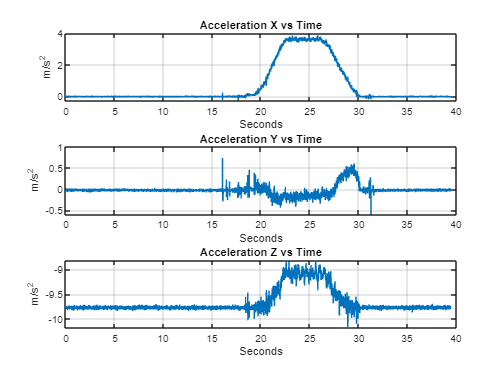

clf;
hold on;

subplot(3,1,1);
plot(time, accel(:, 1));
title("Acceleration X vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

subplot(3,1,2);
plot(time, accel(:, 2));
title("Acceleration Y vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

subplot(3,1,3);
plot(time, accel(:, 3));
title("Acceleration Z vs Time")
xlabel("Seconds")
ylabel("m/s^2")
grid on;

hold off;

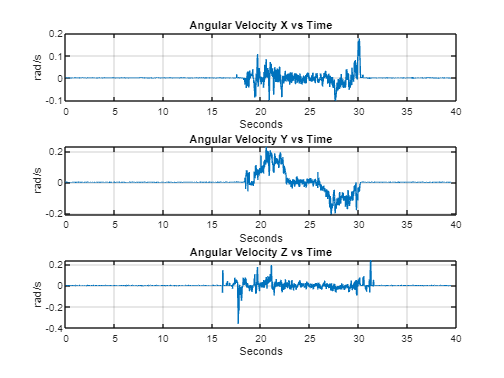

clf;
hold on;

subplot(3,1,1);
plot(time, gyro(:, 1));
title("Angular Velocity X vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

subplot(3,1,2);
plot(time, gyro(:, 2));
title("Angular Velocity Y vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

subplot(3,1,3);
plot(time, gyro(:, 3));
title("Angular Velocity Z vs Time")
xlabel("Seconds")
ylabel("rad/s")
grid on;

hold off;

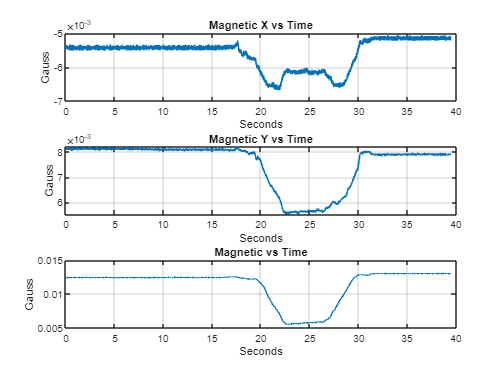

clf;
hold on;

subplot(3,1,1);
plot(time, mag(:, 1));
title("Magnetic X vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

subplot(3,1,2);
plot(time, mag(:, 2));
title("Magnetic Y vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

subplot(3,1,3);
plot(time, mag(:, 3));
title("Magnetic vs Time")
xlabel("Seconds")
ylabel("Gauss")
grid on;

hold off;